Graph generation (STILL NEED TO LOOPIFY THIS PROPERLY)

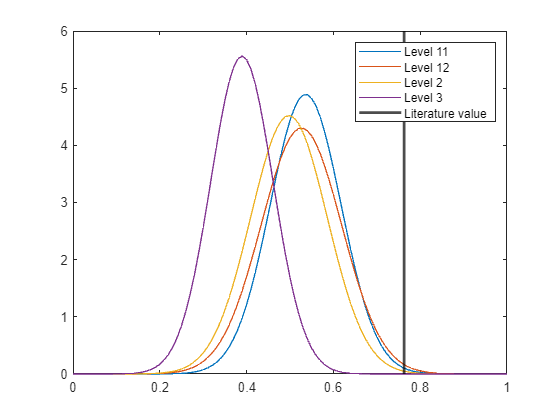

clear  all
% Values from paper
L11_q = 0.762841;
L12_q = 0.689760;
L2_q = 0.555778;
L3_q = 0.296565;

data = importdata("data\base\level_11_q.txt");
importfiltered = data(3:length(data));
importq = data(1);
importvar = data(2);

data1 = importdata("data\base\level_12_q.txt");
importfiltered1 = data1(3:length(data1));
importq1 = data1(1);
importvar1 = data1(2);

data2 = importdata("data\base\level_2_q.txt");
importfiltered2 = data2(3:length(data2));
importq2 = data2(1);
importvar2 = data2(2);

data3 = importdata("data\base\level_3_q.txt");
importfiltered3 = data3(3:length(data3));
importq3 = data3(1);
importvar3 = data3(2);

%histogram(importfiltered)
%bins = histcounts(importfiltered)
normalpd = fitdist(importfiltered, "Normal");
normalpd1 = fitdist(importfiltered1, "Normal");
normalpd2 = fitdist(importfiltered2, "Normal");
normalpd3 = fitdist(importfiltered3, "Normal");
xvalues = 0:0.01:1;
Apdf = pdf(normalpd, xvalues);
Bpdf = pdf(normalpd1, xvalues);
Cpdf = pdf(normalpd2, xvalues);
Dpdf = pdf(normalpd3, xvalues);
A = plot(xvalues, Apdf, 'DisplayName', 'Level 11');
hold on
B = plot(xvalues, Bpdf, 'DisplayName', 'Level 12');
C = plot(xvalues, Cpdf, 'DisplayName', 'Level 2');
D = plot(xvalues, Dpdf, 'DisplayName', 'Level 3');

x1 = xline(L11_q, 'DisplayName', 'Literature value');
x1.LineWidth = 2;
x1.Color = "black";

legend